# Brazo Robot

Dificultad: Normal (Ejemplos)

### Introducción

- Robot Lost-Cost para montar por el alumno y controlar sus movimientos

- Los motores de las articulaciones están controlados en arduino.

- Se ha modelado el robot en SolidWord para obtener su diagrama URDF.

- Se ha diseñado su cinemática directa e inversa en SimScape y Robotic Toolbox.

clear all
close all


### Descripción de la planta

- Robot sobre un tablero de ajedrez

- Piezas que dependen del tablero y otras que dependen de la base.

- El robot está movido respecto del origen total.

- Movimientos absolutos respecto al origen, movimientos relativos respecto al tablero.

- Tomar y dejar piezas.

deg= pi/180;
Estacion= 'C25S4_RobotCasero';
% Se inicia la clase con el robot con el interface de simulink
% VER VERSIÓN SIMULINK
% Variables de simulink

% Posición inicial del robot y del rastreador
% Estas variables van a ser usadas por los objetos Kin como variables del sistema 
% No deben modificarse en el programa 
q0_= zeros(1,7);
pose_= randn(3,3)*1e-3;

% Posición de la base del robot
baseRobot= [[0,0,20]*1e-3, [0,0,0]*deg];
% Posición de la base del robot

% Posible carga del robot
Carga= Pieza('Null');
Carga.Base([[0,0,0]*1e-3, [0,0,0]*deg]);
Carga.Tcp([[0,0,0]*1e-3, [0,0,0]*deg]);
Carga.Color([0,0,0,0.1]);

% Icono fijo
TabAje= Pieza();
TabAje.Base([[-150,-200, 20]*1e-3, [0,0,0]*deg]);
% La salida se ajusta a la primera casilla 
TabAje.Tcp([[25,25,7]*1e-3,[0,0,0]*deg]);
TabAje.Color([0.3, 0.8, 0.2, 0.7]);

% Icono variable
pTab1= Pieza('Torre');
Px= 4; Py= 2;
pTab1.Base([[50*Px, 50*Py, 0]*1e-3, [0,0,0]*deg])
pTab1.Color([1,1,1,1]);

% Icono variable
pTab2= Pieza('Caballo');
Px= 3; Py= 5;
pTab2.Base([[50*Px, 50*Py, 0]*1e-3, [0,0,0]*deg])
pTab2.Color([0,0,0,1]);

% Icono variable
pTab3= Pieza('Rey');
Px= 5; Py= 5;
pTab3.Base([[50*Px, 50*Py, 0]*1e-3, [0,0,0]*deg])
pTab3.Color([0,0,0,1]);

pExt1= Pieza('Torre');
pExt1.Base([[175,0,25]*1e-3, [0,0,0]*deg]);
pExt1.Color([0,0,0,0.9]);

pExt2= Pieza('Null');
pExt2.Base([[0,0,0]*1e-3, [0,0,0]*deg]);
pExt2.Color([0,0,0,0.2]);

open_system(Estacion)
% Paso de la estación de simulink al objeto Rigid Body (Robotic Toolbox)
robot= importrobot(Estacion);
robot.showdetails

--------------------
Robot: (10 bodies)

 Idx     Body Name     Joint Name     Joint Type     Parent Name(Idx)   Children Name(s)
 ---     ---------     ----------     ----------     ----------------   ----------------
   1        Body01        Joint01          fixed              Base(0)   Body02(2)  
   2        Body02        Joint02       revolute            Body01(1)   Body03(3)  
   3        Body03        Joint03       revolute            Body02(2)   Body04(4)  
   4        Body04        Joint04       revolute            Body03(3)   Body05(5)  
   5        Body05        Joint05       revolute            Body04(4)   Body06(6)  
   6        Body06        Joint06       revolute            Body05(5)   Body07(7)  Body08(8)  Body09(9)  
   7        Body07        Joint07       revolute            Body06(6)   
   8        Body08        Joint08       revolute            Body06(6)   
   9        Body09        Joint09          fixed            Body06(6)   Body10(10)  
  10        Body10      


% El punto TCP es independiente de las pinzas, por lo que su movimiento no
% altera la posición de las pinzas
bodyCarga= 'Body10';

% Se debe definir el rigid-body asociado a la estación, la estación simulink
% la herramienta deseada (última por defecto) y el valor de los ejes
% iniciales q0= [0,0,0,0,0,0] por defecto
q0= zeros(1,7);

rob= Cin(robot, Estacion, bodyCarga, q0);

Herramienta: Body10
Simulación. Ts= 0.100 m/s


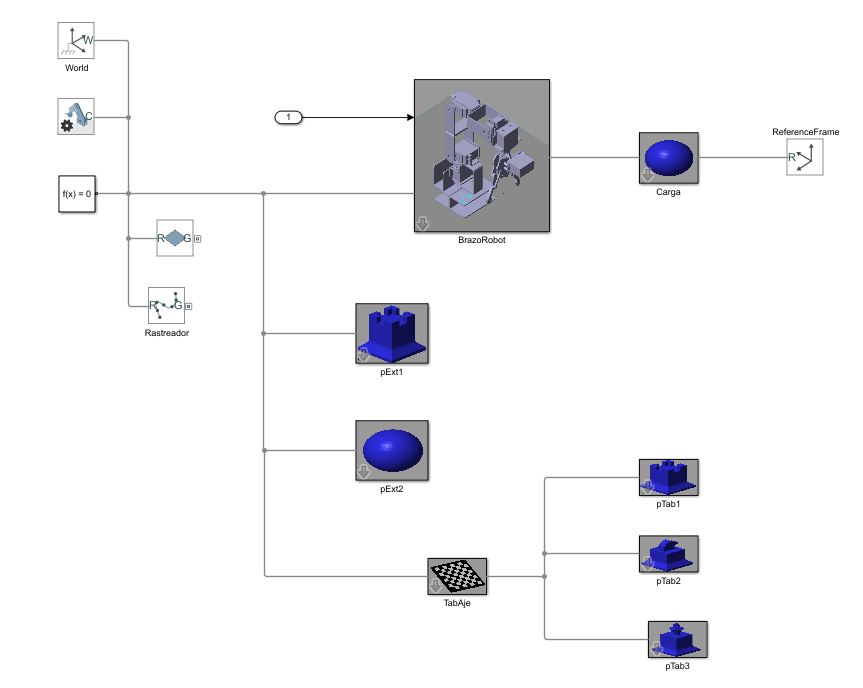

## 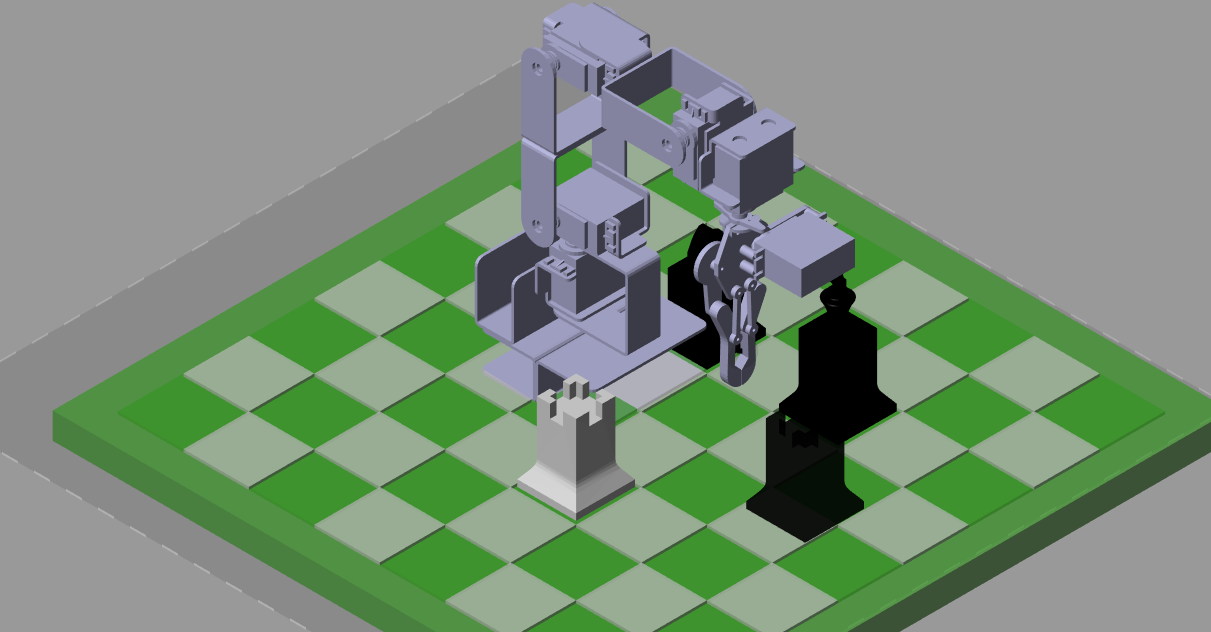

## Movimiento absoluto

- Abro las pinzas con movimiento absoluto

- He quitado un eje, ya que la pinza se abre de forma simétrica

deg= pi/180;

p= 30;
eje= [0,0,0,0,0,p,-p]*deg;
rob.MoveAbsJ(eje);

rob.MoveAbsJ(eje);

### Movimiento por puntos (Toma pieza libre)

- La cinemáticia inversa del TCP no altera la posición de las pinzas.

- Por ello las pinzas se quedan en la posición que tenían.

- Para abrir o cerrar las pinzas hay que dar cinemática directa del los ejes 6 y 7

- La pieza se puede detectar por su posición de la base

deg= pi/180;

p= 30;
eje= [0,0,0,0,0,p,-p]*deg;
rob.MoveAbsJ(eje);

punto= [[0,0,50]*1e-3,[0,0,180]*deg];
% La referencia es la base de la pieza
rob.MoveJ(punto, pExt1.Hbase);

q= rob.Joint;
p= 20;
q(6:7)= [p,-p]*deg;
rob.MoveAbsJ(q);

PegarEn(Carga, pExt1, rob.Pose, [])
p= 20;
eje= [0,0,0,0,0,p,-p]*deg;
rob.MoveAbsJ(eje);


### Dejar pieza en posición con respecto al origen


punto= [[175,0,50+25]*1e-3,[0,0,180]*deg];
rob.MoveJ(punto);

q= rob.Joint;
p= 30;
q(6:7)= [p,-p]*deg;
rob.MoveAbsJ(q);

PegarEn(pExt1, Carga, [], rob.Pose)
p= 30;
eje= [0,0,0,0,0,p,-p]*deg;
rob.MoveAbsJ(eje);


### Movimiento por puntos (Toma pieza tablero)

- La base de la pieza es función del tcp del tablero y la base de la pieza respecto al tablero.

deg= pi/180;

p= 30;
eje= [0,0,0,0,0,p,-p]*deg;
rob.MoveAbsJ(eje);
 
punto= [[0, 0, 50]*1e-3,[0,0,180]*deg];
% La referencia es la base de la pieza
rob.MoveJ(punto, TabAje.Htcp*pTab1.Hbase);

q= rob.Joint;
p= 20;
q(6:7)= [p,-p]*deg;
rob.MoveAbsJ(q);

PegarEn(Carga, pTab1, rob.Pose, TabAje.Htcp)
p= 20;
eje= [0,0,0,0,0,p,-p]*deg;
rob.MoveAbsJ(eje);

### Deja en el mismo punto

- Cada casilla del tablero mide 50 mm.

deg= pi/180;

p= 20;
eje= [0,0,0,0,0,p,-p]*deg;
rob.MoveAbsJ(eje);

Px= 4; Py= 2; 
punto= [[Px*50, Py*50, 50]*1e-3,[0,0,180]*deg];
% La referencia es la base de la pieza
rob.MoveJ(punto, TabAje.Htcp);

q= rob.Joint;
p= 30;
q(6:7)= [p,-p]*deg;
rob.MoveAbsJ(q);

PegarEn(pTab1, Carga, TabAje.Htcp, rob.Pose)
p= 30;
eje= [0,0,0,0,0,p,-p]*deg;
rob.MoveAbsJ(eje);


### Usar la herramienta appMover

- Se puede usar esta herramienta para mover el robot o alguna pieza de la estación.

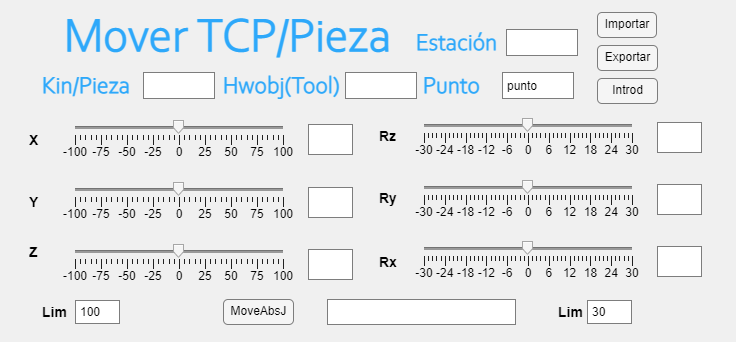

appMover